clear all, close all, clc;

% Import data from text file
% Script for importing data from the following text file:
%
%    filename: observerComparism2.csv
%
% Auto-generated by MATLAB on 13-Apr-2023 18:01:37

## Constants

FIRST_SAMPLE_IDX = 1600;
LAST_SAMPLE_IDX = 8500;

## Set up the Import Options and import the data

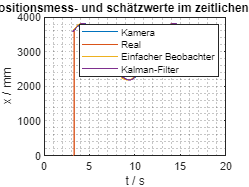


opts = delimitedTextImportOptions("NumVariables", 5, "Encoding", "UTF-8");

% Specify range and delimiter
opts.DataLines = [FIRST_SAMPLE_IDX, LAST_SAMPLE_IDX];
opts.Delimiter = ";";

% Specify column names and types
opts.VariableNames = ["t", "xObs", "xRef", "xCam", "xKalman"];
opts.VariableTypes = ["double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
tbl = readtable("observerComparism2.csv", opts);

% Convert to output type
t = tbl.t / 1000;
xObs = tbl.xObs;
xRef = tbl.xRef;
xCam = tbl.xCam;
xKalman = tbl.xKalman;

% Clear temporary variables
clear opts tbl

%clean cam data from zeros and linear interpolation
xCam = filloutliers(xCam, "linear");

%Kreisfahrt 103.3864ms  Sinusfahrt 160.3870ms   WallCrash 106ms --> Mean
%123.2578ms (61cycles)
delayCycles = 61;
xReal = circshift(xCam, -delayCycles);
xReal(1:delayCycles) = 0;



plot(t, xCam, t, xReal, t, xObs, t, xKalman);
grid minor;
legend('Kamera', 'Real', 'Einfacher Beobachter', 'Kalman-Filter');
xlabel("t / s"), ylabel("x / mm");
title("Alle Positionsmess- und schätzwerte im zeitlichen Vergleich")



% Korrelationen
t = t - t(1);
x = t(1:5000);

seObs = zeros(1000, 5000);
sseObs = zeros(1, 1000);
seKalman = zeros(1000, 5000);
sseKalman = zeros(1, 1000);
seCam = zeros(1000, 5000);
sseCam = zeros(1, 1000);

for delay = [1:1000]
    seCam(delay, :) = (xReal(delay+delayCycles:delay+delayCycles+5000-1) - xCam(delayCycles:5000+delayCycles)).^2;
    sseCam(delay) = sum(seCam(delay, :));
    seObs(delay, :) = (xCam(delay:delay+5000-1) - xObs(1:5000)).^2;
    sseObs(delay) = sum(seObs(delay, :));
    seKalman(delay, :) = (xCam(delay:delay+5000-1) - xKalman(1:5000)).^2;
    sseKalman(delay) = sum(seKalman(delay, :));
end

Arrays have incompatible sizes for this operation.

Related documentation


sseCam = sseCam / max(sseCam);
rCam = 1 - sseCam;
sseObs = sseObs / max(sseObs);
rObs = 1 - sseObs;
sseKalman = sseKalman / max(sseKalman);
rKalman = 1 - sseKalman;

plot(x(1:1000), rCam, x(1:1000), rObs, x(1:1000), rKalman)
grid minor
xlabel("t / s"), ylabel("r")
title("Korrelation von Kamera- und Kalman-Beobachterdaten für verschiedene Zeitverzögerungswerte")
legend("Cam","Einfacher Beobachter", "Kalman-Filter")

[rMaxKalman, delayInCyclesKalman] = max(rKalman);
[rMaxObs, delayInCyclesObs] = max(rObs);

delayInMsKalman = delayInCyclesKalman * 2;
delayInMsObs = delayInCyclesObs * 2;
